# RTD Activity 1 

Rango_temp=0:1:800

Rango_temp =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


A=3.903e-3

A = 0.0039

B=-5.77e-7

B = -5.7700e-07

Ro = 100 %Resistencia nominal 

Ro = 100



Rt_1=Ro*(1+A*Rango_temp)%lineal

Rt_1 =   100.0000  100.3903  100.7806  101.1709  101.5612  101.9515  102.3418  102.7321  103.1224  103.5127  103.9030  104.2933  104.6836  105.0739  105.4642  105.8545  106.2448  106.6351  107.0254  107.4157  107.8060  108.1963  108.5866  108.9769  109.3672  109.7575  110.1478  110.5381  110.9284  111.3187  111.7090  112.0993  112.4896  112.8799  113.2702  113.6605  114.0508  114.4411  114.8314  115.2217  115.6120  116.0023  116.3926  116.7829  117.1732  117.5635  117.9538  118.3441  118.7344  119.1247


Rt_n1=Ro*(1+A.*(Rango_temp)+B.*(Rango_temp.^2)) %nolineal

Rt_n1 =   100.0000  100.3902  100.7804  101.1704  101.5603  101.9501  102.3397  102.7293  103.1187  103.5080  103.8972  104.2863  104.6753  105.0641  105.4529  105.8415  106.2300  106.6184  107.0067  107.3949  107.7829  108.1709  108.5587  108.9464  109.3340  109.7214  110.1088  110.4960  110.8832  111.2702  111.6571  112.0439  112.4305  112.8171  113.2035  113.5898  113.9760  114.3621  114.7481  115.1339  115.5197  115.9053  116.2908  116.6762  117.0615  117.4467  117.8317  118.2166  118.6015  118.9862




%Relative error
error_relativo= ((Rt_1-Rt_n1)./Rt_n1)*100

error_relativo =          0    0.0001    0.0002    0.0005    0.0009    0.0014    0.0020    0.0028    0.0036    0.0045    0.0056    0.0067    0.0079    0.0093    0.0107    0.0123    0.0139    0.0156    0.0175    0.0194    0.0214    0.0235    0.0257    0.0280    0.0304    0.0329    0.0354    0.0381    0.0408    0.0436    0.0465    0.0495    0.0526    0.0557    0.0589    0.0622    0.0656    0.0691    0.0726    0.0762    0.0799    0.0837    0.0875    0.0914    0.0954    0.0995    0.1036    0.1078    0.1121    0.1164


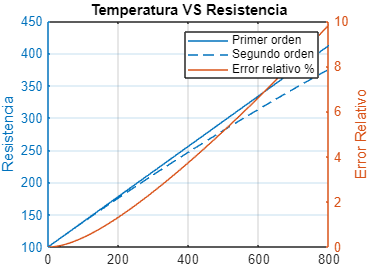


figure; 
%comando para colocar dos ejes Y
yyaxis("left")
plot(Rango_temp,Rt_1)
hold on;
plot(Rango_temp,Rt_n1)
ylabel("Resistencia")

%para eje derecho
yyaxis("right")
plot(Rango_temp,error_relativo)
ylabel("Error Relativo")

title("Temperatura VS Resistencia")
grid on 

legend("Primer orden","Segundo orden","Error relativo %")